clear;

Nvar = 2;
Nmax = 50;
errodf = 15e-3;
NPontosIniciais = 7;
x_values=[-11;-11]; y_values=[7;7];

PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2; lambda = 0.000005;

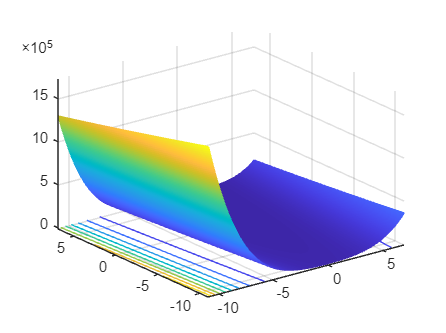

[Lista, LNit, Lopt] = steepest_descent_static(r, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

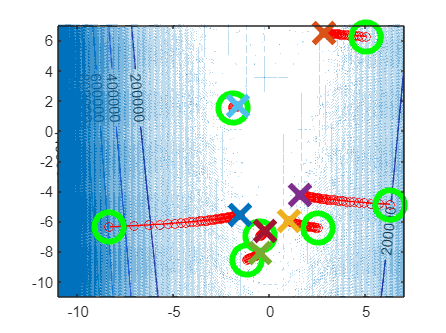


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

[Lista, LNit, Lopt] = steepest_descent_wolfe(r, Nmax, errodf, PontosIniciais, x_values, y_values);

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

[Lista, LNit, Lopt] = newton_raphson(r, Nmax, errodf, PontosIniciais, x_values, y_values);

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

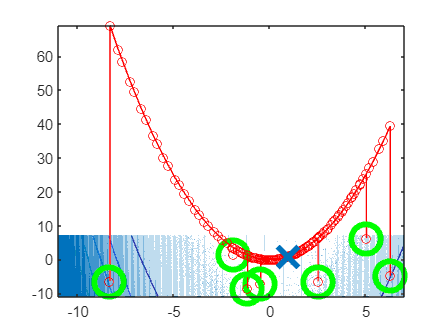


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off